imgs_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


labels_files = 1486×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


ans =          512         512           3        1486


ans =          512         512           3        1486


accur =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


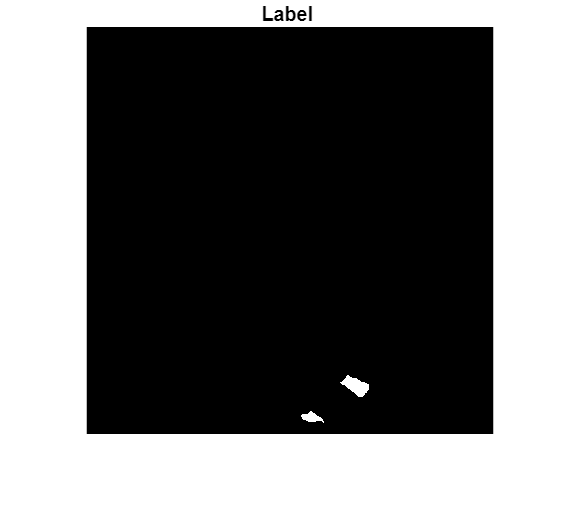

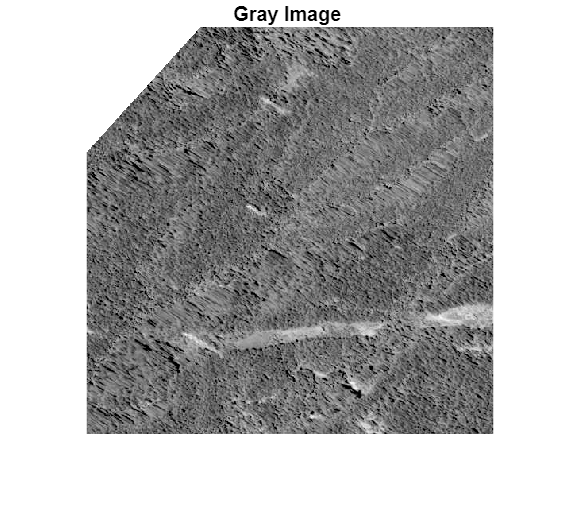

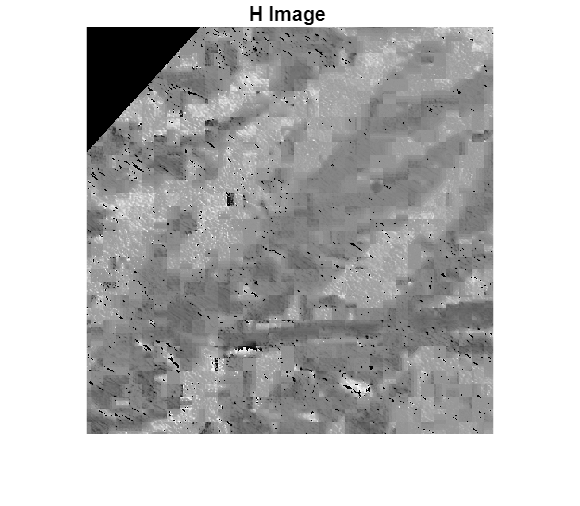

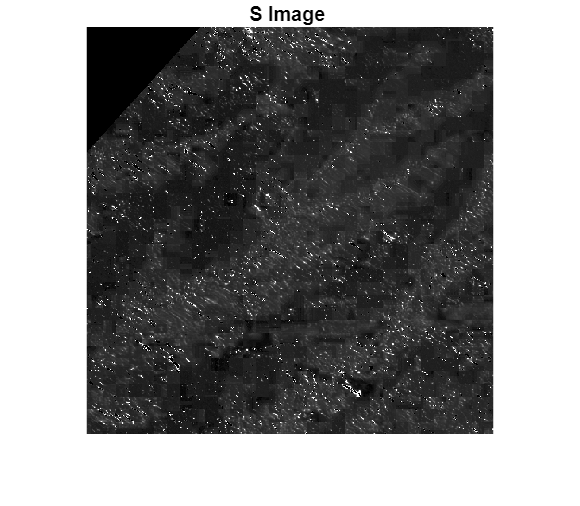

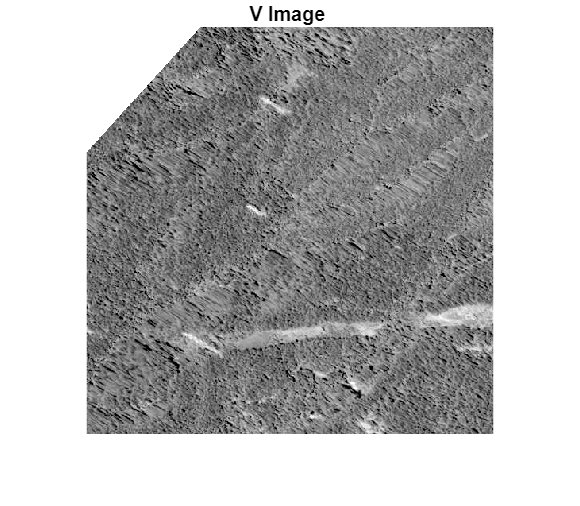

mask_landslide =     0.7362    1.3645    0.8150    0.8099


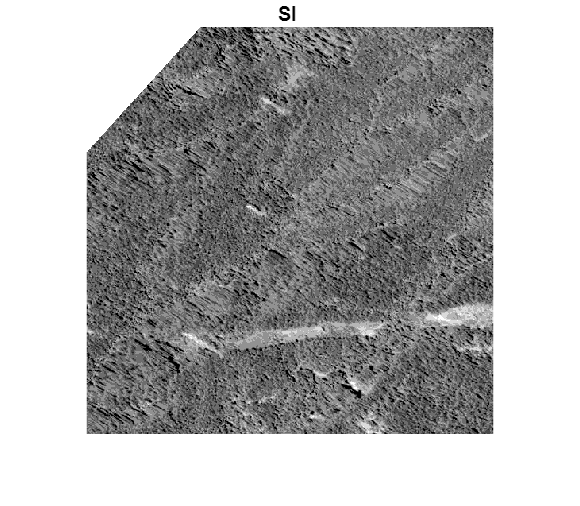

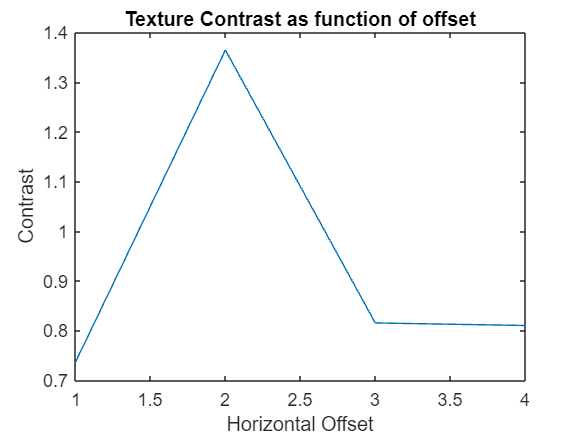

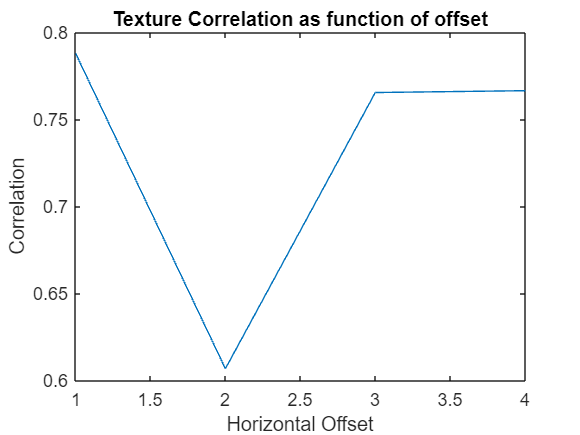

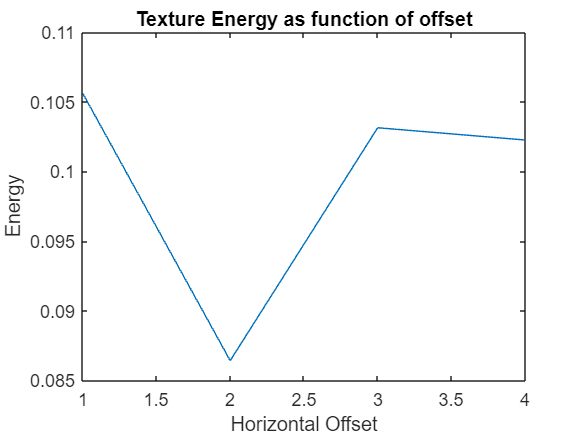

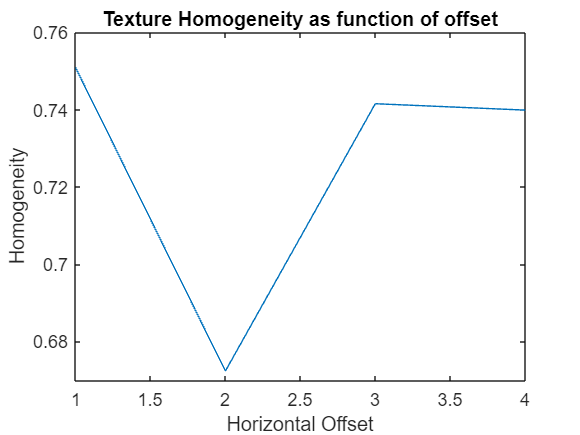

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)
labels_files=dir(label_directory)
imgs = zeros(512,512,3,length(imgs_files),'uint8');
labels = zeros(512,512,3,length(imgs_files),'uint8');
for i=1:length(imgs_files)
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)
size(labels)

t1 = datetime('now');
accur = zeros(1,size(imgs,4))
for i=1%:size(imgs,4)
    % Read image
    img = imgs(:,:,:,i);
    label = labels(:,:,:,i);
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    img_gray = rgb2gray(img);
    img_hsv = rgb2hsv(img);
    
    % Determine what provides most promininent landlside features
    figure;
    imshow(label);
    title('Label ',i);
    figure;
    imshow(img_gray);
    title('Gray Image ',i);
    figure;
    imshow(img_hsv(:,:,1));
    title('H Image ',i);
    figure;
    imshow(img_hsv(:,:,2));
    title('S Image ',i);
    figure;
    imshow(img_hsv(:,:,3));
    title('V Image ',i);

    offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions
    [glcm, SI] = graycomatrix(img_gray, Offset=offsets); %, Symmetric=true);
    stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
    % High contrast is rough terrain (landlside)
    % Low E is more randomness (lanslide distrutpins)
    % High homogeneirty is uniform areas (vegetation or stable land)

    mask_landslide = stats.Contrast

    figure;
    imshow(rescale(SI));
    title('SI ',i);

    figure, plot([stats.Contrast]);
    title('Texture Contrast as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Contrast');
    figure, plot([stats.Correlation]);
    title('Texture Correlation as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Correlation');
    figure, plot([stats.Energy]);
    title('Texture Energy as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Energy');
    figure, plot([stats.Homogeneity]);
    title('Texture Homogeneity as function of offset');
    xlabel('Horizontal Offset');
    ylabel('Homogeneity');
end

clear all
% Setup
dataset_directory = "C:\Users\andre\Year5\EE581\Project\Datasets\Full_CAS\Hokkaido Iburi-Tobu";
img_directory = dataset_directory + "\img\";
label_directory = dataset_directory + "\label\";
mask_directory = dataset_directory + "\mask\";

% Store all images and labels
imgs_files=dir(img_directory)
labels_files=dir(label_directory)
imgs = zeros(512,512,3,1184,uint8');
labels = zeros(512,512,3,1184,'uint8');
for i=3:1186
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end
size(imgs)
size(labels)

% Init
feautresMatrix = [];
labelsVec = [];
window_size = 10;
offsets = [0 1; -1 1; -1 0; -1 -1]; % Different directions

t1 = datetime('now');

for i=1%:size(imgs,4)
    % Read image
    img = imgs(:,:,:,i);
    img_gray = rgb2gray(img);

    % Read Ground Truth Label (Binary Mask)
    label = labels(:,:,:,i);
    % Invert label
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    
    % Img dimens
    [rows, cols] = size(img_gray);

    % Slide over img with 10x10 window
    for r = 1:window_size:rows-window_size
        for c = 1:window_size:cols-window_size
            % Extract window
            window = img_gray(r:r+window_size-1, c:c+window_size-1);
            label_window = label(r:r+window_size-1, c:c+window_size-1);

            % Compute GLCM features
            glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
            stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
            
            % Store features
            features = [mean(stats.Contrast), mean(stats.Correlation), ...
                mean(stats.Energy), mean(stats.Homogeneity),];
            featuresMatrix = [featuresMatrix; features]; % Append row
        
            % Assing label - if 10% of pix in label is 1, mark as landlside
            if sum(label_window,'all') >= (window_size*window_size/10)
                label = 1; % Landlside present
            else
                label = 0; % No landslide
            end
            labelsVec = [labelsVec; label] % Append label
        end
    end
end
% Save dataset for training
save('C:/Users/andre/Year5/EE581/Project/Scripts/landslide_features_dataset.mat', 'featuresMatrix','labelsVec')
disp('Sliding window feature extraction completed and saved.');

%% Now train SVM classifier with localisex feature vectors (classify if 10x10 
% portion of image is landlside via the features)

% Train SVM model
svmModel = fitcsvm(featuresMatrix, labelsVec, 'KernelFunction','linear'); % Maybe rbf

% Save trained model
save('C:/Users/andre/Year5/EE581/Project/Scripts/svm_landslide_model.mat', 'svmModel');
disp('SVM trained and model saved');

t2 = datetime('now');
dt = between(t1,t2)

%% Classify portions of new image

imgs = zeros(512,512,3,300,uint8');
labels = zeros(512,512,3,300,'uint8');
for i=1187:1486
    if imgs_files(i).name(1) == 'H'
        imgs(:,:,:,i-2) = double(imread(img_directory + imgs_files(i).name));
    end
    if labels_files(i).name(1) == 'H'
        labels(:,:,:,i-2) = double(imread(label_directory + labels_files(i).name));
    end
end

t1 = datetime('now');
accur = zeros(1,size(imgs,4))
for i=1%:size(imgs,4)
    % Init result mask
    results_mask = zeros(rows,cols);
    
    % Read image
    img = imgs(:,:,:,i);
    img_gray = rgb2gray(img);

    % Read Ground Truth Label (Binary Mask)
    label = labels(:,:,:,i);
    % Invert label
    label_= label;
    label_(label_ == 255) = 1;
    label_bin = (label_(:,:,1) + label_(:,:,2) + label_(:,:,3)) > 0;
    label = 1 - label_bin;    
    
    % Img dimens
    [rows, cols] = size(img_gray);

    % Slide over img with 10x10 window
    for r = 1:window_size:rows-window_size
        for c = 1:window_size:cols-window_size
            % Extract window
            window = img_gray(r:r+window_size-1, c:c+window_size-1);
            % label_window = label(r:r+window_size-1, c:c+window_size-1); -
            % use to determine how many times it is accurate with landslide
            % region

            % Compute GLCM features
            test_glcm = graycomatrix(window, Offset=offsets); %, Symmetric=true);
            test_stats = graycoprops(test_glcm, {'Contrast', 'Correlation', 'Energy', 'Homogeneity'}); 
            test_features = [mean(test_stats.Contrast), mean(test_stats.Correlation), ...
                mean(test_stats.Energy), mean(test_stats.Homogeneity),];
            
            % Predict Landlside or not
            predLabel = predict(svmModel, test_features);

            % Store result in mask
            if predLabel == 1
                resultMask(r:r+window_size-1,c:c+window_size-1) = 1; % Mark landlside area
            end
        end
    end
    % % Display results
    % subplot(1,2,1); imshow(img_gray); title('Original Image');
    % subplot(1,2,2); imshow(result_mask, []); title('Predicted Landslide Regions');

    [x_lbl, y_lbl] = find(label);
    count = 0;
    for k=1:length(x_lbl)
        if(resultMask(x_lbl(k),y_lbl(k))) == 1
            count = count + 1; % Correctly identified landlside - should also do one for the non-landslide
        end
    end
    similarity = count / length(x_lbl) * 100;
    accur(1,i) = similarity;
    imwrite(Mask_HV_denoised_open,sprintf('C:/Users/andre/Year5/EE581/Project/Datasets/Full_CAS/Hokkaido Iburi-Tobu/Pred/Pred2_%d.jpg',i));
end
figure;
plot(1:length(accur),accur);
xlabel('Index');
ylabel('Percentage [%]');
title('Accuracy')
grid on;
t2 = datetime('now');
dt = between(t1,t2)